## Include Parameters or Data

Numberofvariables=6;
lowerbounds=[0 0.05 0.05 0 0 0];
upperbounds=[1 1 1 1 1 1];

## Optimize Live Editor Task

Optimization terminated: maximum number of generations exceeded.


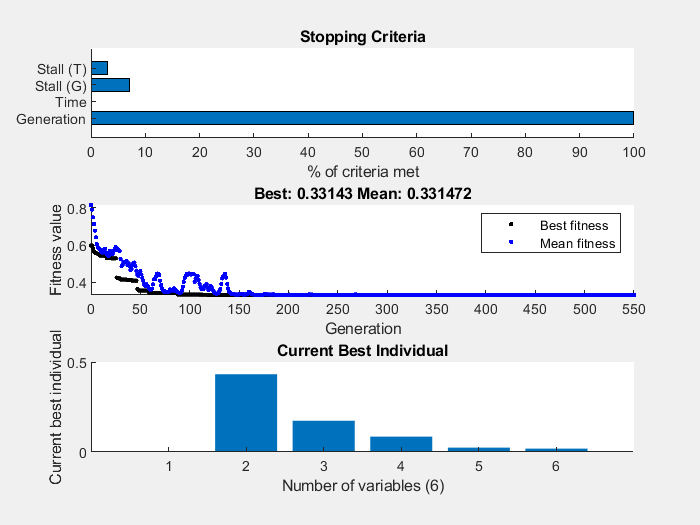

% Set nondefault solver options
options = optimoptions("ga","PopulationSize",200,"MaxGenerations",550,...
    "MaxStallGenerations",500,"MaxStallTime",200,"PlotFcn",["gaplotstopping",...
    "gaplotbestf","gaplotbestindiv"]);

% Solve
[solution,objectiveValue] = ga(@CalcAvGamma3,Numberofvariables,[],[],[],[],...
    lowerbounds,upperbounds,[],[],options);


% Clear variables
clearvars options

## Results

p=solution

p =     0.0000    0.4319    0.1739    0.0851    0.0245    0.0188
